# Setting up the Stage:

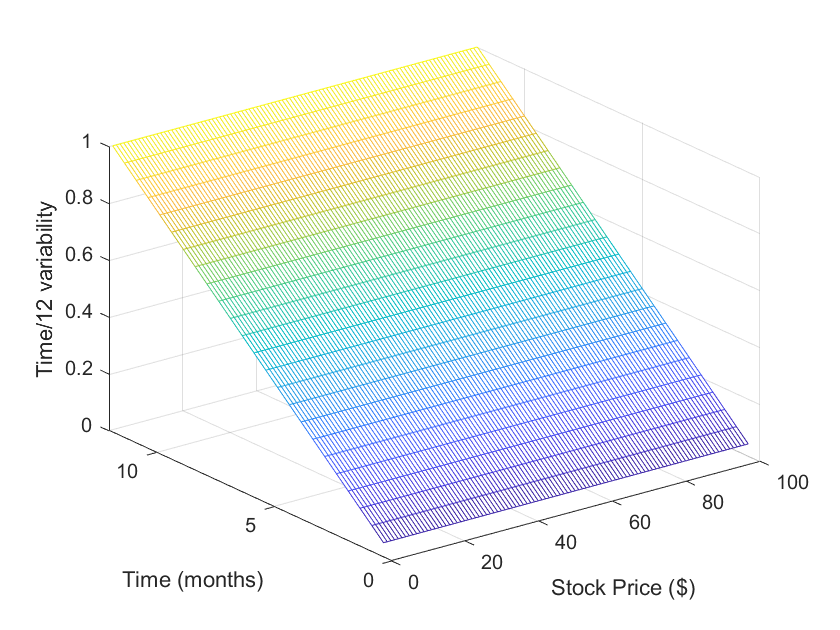

prices = 1:100;                   % Range of Stock Price
span = length(prices);            % Scalar value, span=100

time = 0.5:0.5:12;                % Half-Month per stime period
New0 = time(ones(span,1),:)'/12;  % Transposed, /12
mesh(prices, time, New0);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Time/12 variability');

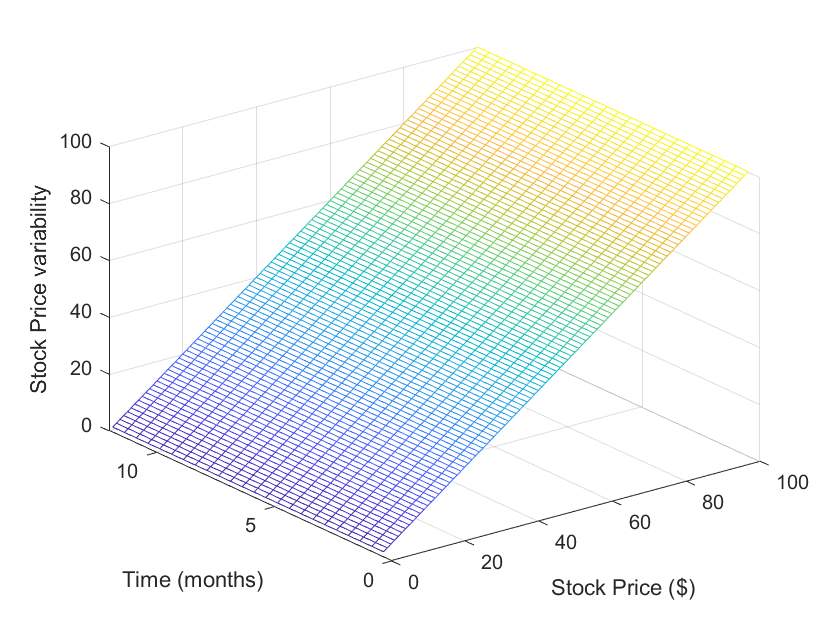

% New0 is the floor of (time,time,.....100times) for 100 stock prices

time_ones=ones(length(time),1);
New1 = prices(time_ones,:);
mesh(prices, time, New1);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Stock Price variability');

% New1 is the floor of (prices;prices;....24times) for 24 time periods

floor = ones(size(New0));
% floor is the ones matrix of New0 or New1 dimensions

# GREEKS

## DELTA

**Definition: **The rate of change of option price with respect to the price of underlying asset.

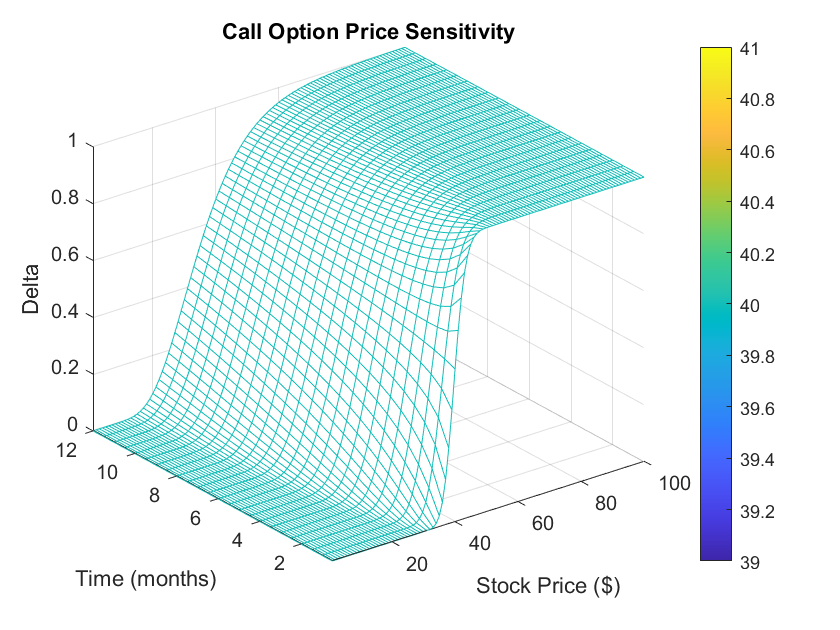

% [Call_Delta,Put_Delta] = blsdelta(SO,X,R,T,SIG,Q)
% S0 is current stock price  ~ New1
% X is the excercise price
% R is the risk free rate
% T is the time to maturity  ~ New0
% SIG is the volatility
% Q is the dividend rate or foreign interest (= 0 by default)
X = 40;
R = 0.1;
Vol = 0.35;
[Call_delta,Put_delta] = blsdelta(New1, X*floor, R*floor, New0, Vol*floor);
mesh(prices, time, Call_delta, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)'); 
zlabel('Delta');
title('Call Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

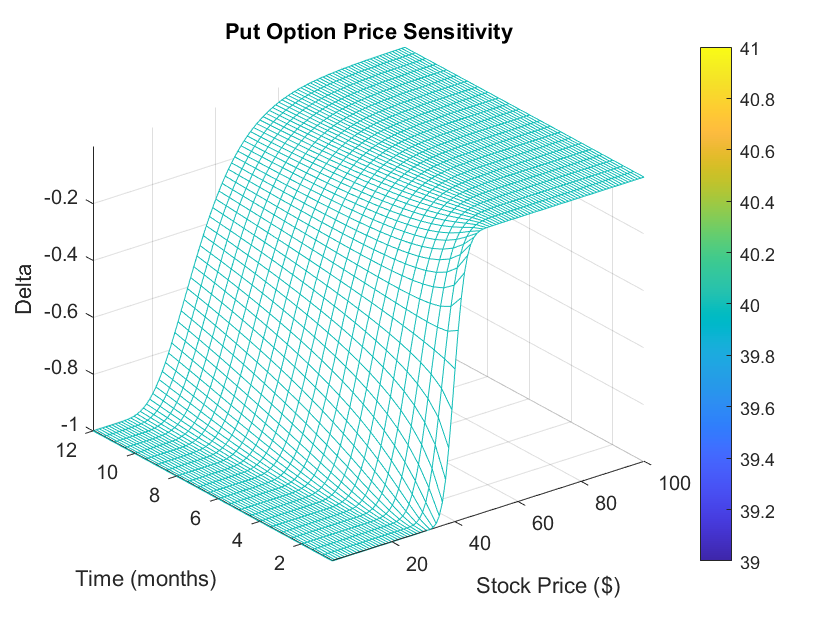

%Scale shows the Strike Price value = 40

mesh(prices, time, Put_delta, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Delta');
title('Put Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

%Scale shows the Strike Price value = 40

## GAMMA

Definition: The rate of change of delta with respect to the price of underlying asset.

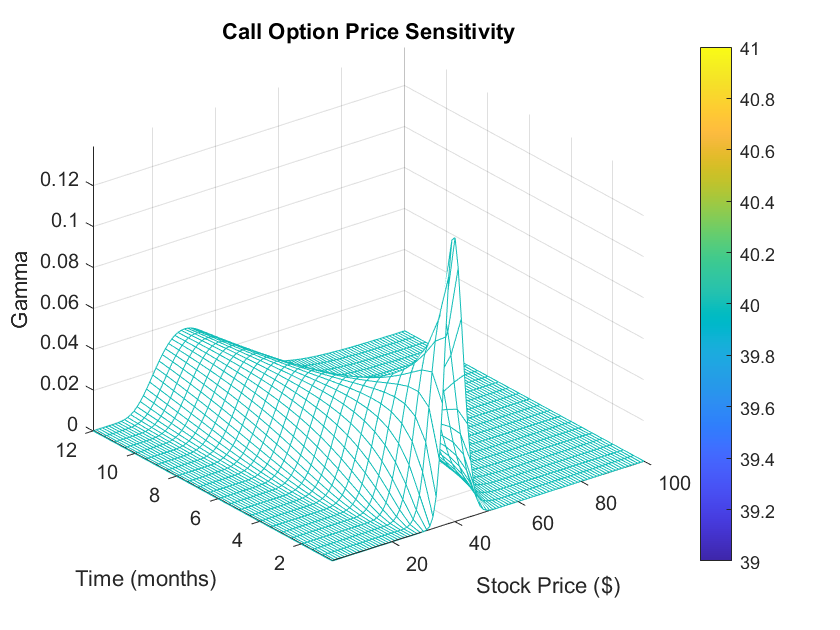

gamma = blsgamma(New1, X*floor, R*floor, New0, Vol*floor);
mesh(prices, time, gamma, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Gamma');
title('Call Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

%Scale shows the Delta value = 40

## THETA

Definition: The rate of change of option price with respect to the time.

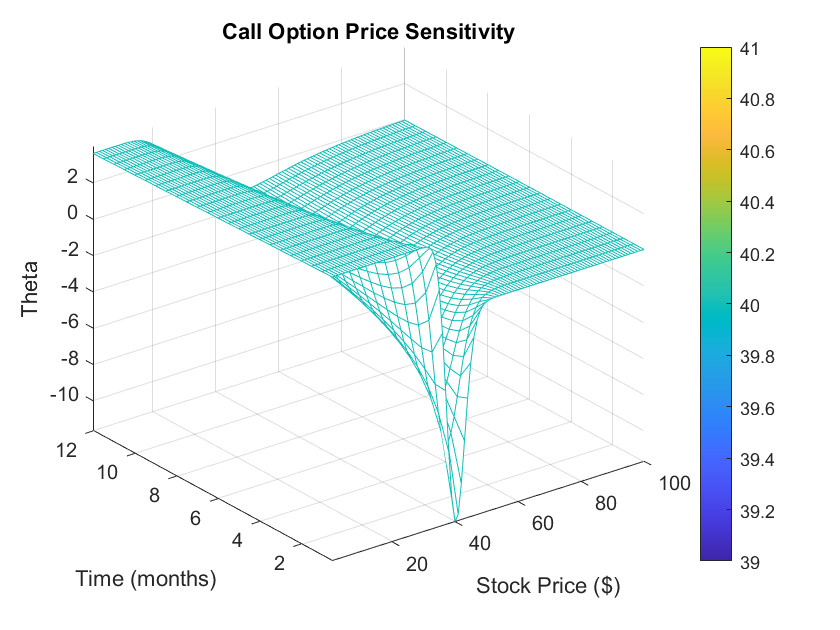

[call_theta,put_theta] = blstheta(New1, X*floor, R*floor, New0, Vol*floor);
mesh(prices, time, put_theta, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Theta');
title('Call Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

%Scale shows the Strike Price value = 40

## RHO

Definition: The rate of change of option price with respect to the risk free rate of interest

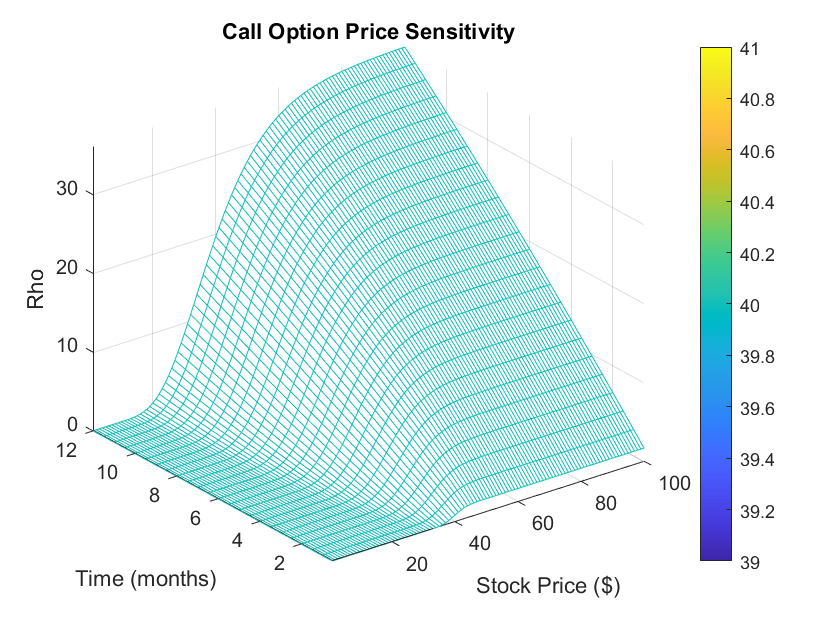

rho = blsrho(New1, X*floor, R*floor, New0, Vol*floor);
mesh(prices, time, rho, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Rho');
title('Call Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

%Scale shows the Strike Price value = 40

## VEGA

Definition: The rate of change of option price with respect to the Volatility.

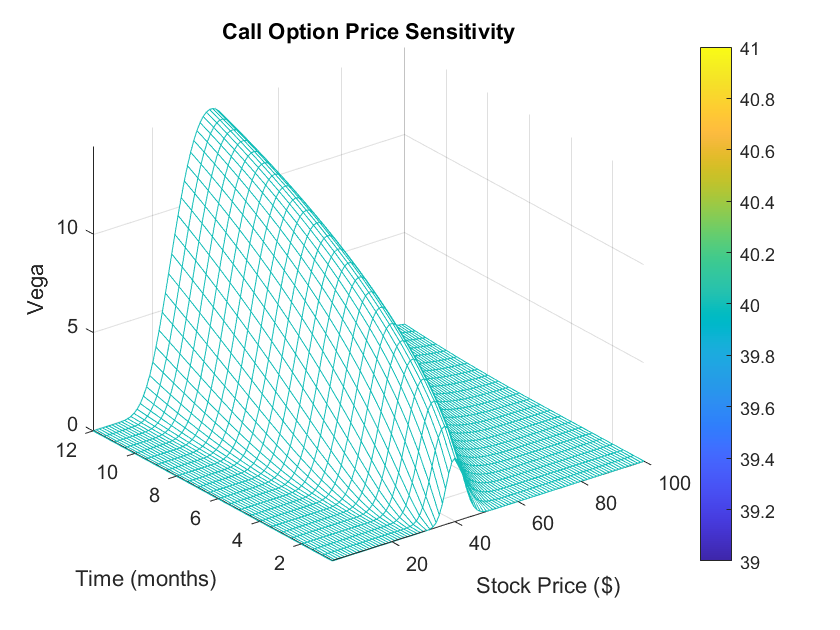

Vega = blsvega(New1, X*floor, R*floor, New0, Vol*floor);
mesh(prices, time, Vega, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Vega');
title('Call Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

%Scale shows the Strike Price value = 40

## LAMBDA

Definition: The rate of change option price with respect to the Stock price. Elasticity of an option.

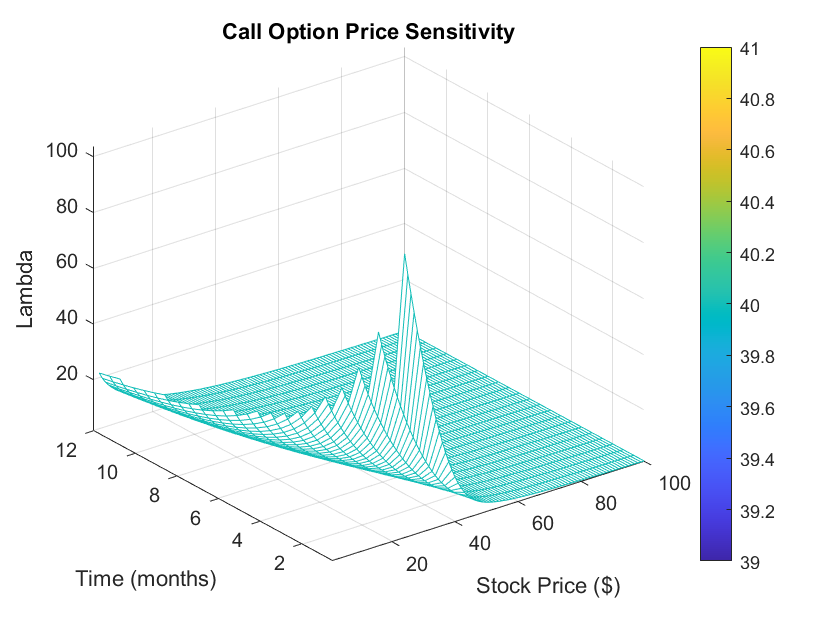

Lambda = blslambda(New1, X*floor, R*floor, New0, Vol*floor);
mesh(prices, time, Lambda, X*floor);
xlabel('Stock Price ($)');
ylabel('Time (months)');
zlabel('Lambda');
title('Call Option Price Sensitivity');
axis([1 100  0.5 12  -inf inf]);
colorbar;

%Scale shows the Strike Price value = 40

.